## Linear Regression

A linear regression filter learns by adjusting weights.

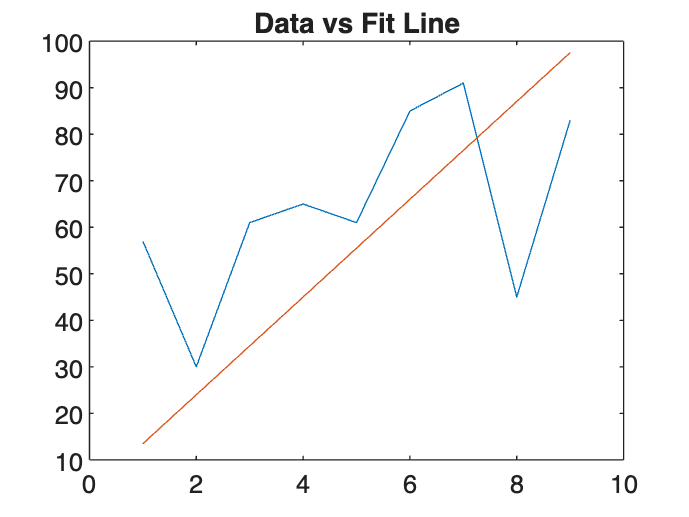

file = readmatrix("./linearRegression.csv");
input = file(:,1);
measurement = file(:,2);
damping = 0.009;

[outputs, weights, initialStates] = linearRegressionFilter( ...
    input, ...
    measurement, ...
    damping ...
);

plot(input, measurement, input, outputs);
title('Data vs Fit Line');

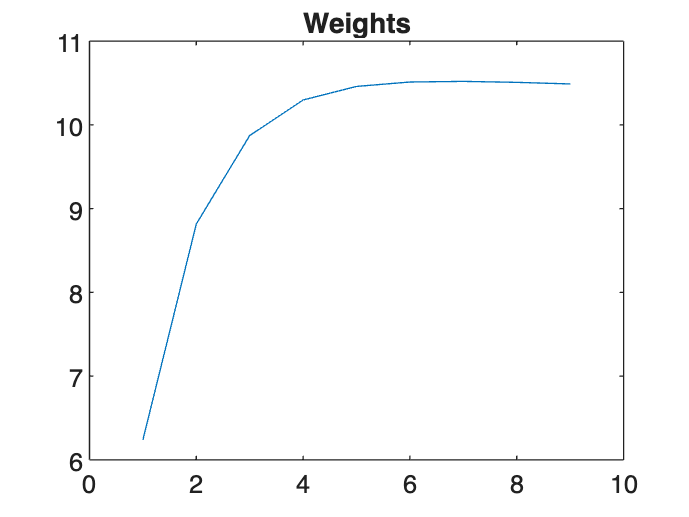


plot(input, weights);
title('Weights');

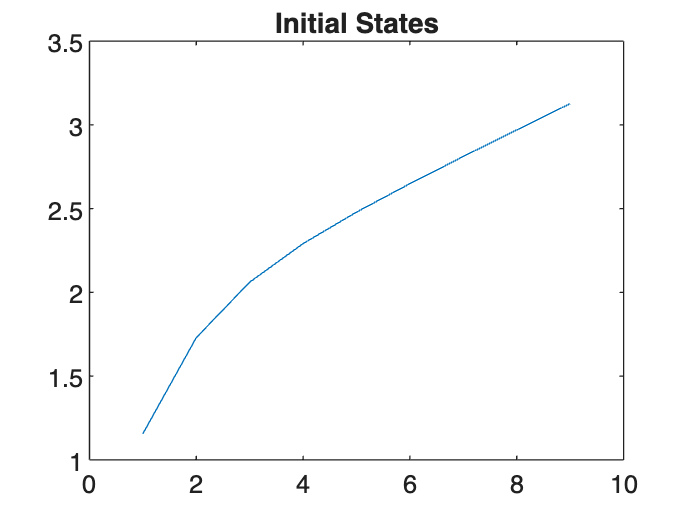


plot(input, initialStates);
title('Initial States');

function [ ...
    outputs, weights, initialStates ...
] = linearRegressionFilter( ...
    xInput, ...
    yInput, ...
    damping ...
)
  % Weight of input on output
  weight = 0;
  weights = zeros(length(xInput), 1);
  initialStates = zeros(length(xInput), 1);

  % Initial state
  initialState = 0;

  for n = 1:length(xInput)
    % Predict
    % y = wx + b
    predictions = weight * xInput + initialState;

    % Correct weight
    deltaWeight = -2 * mean(xInput .* (yInput - predictions));
    weight = weight - deltaWeight * damping;
    weights(n) = weight;

    % Correct initial state
    deltaState = -2 * mean(yInput - predictions);
    initialState = initialState - deltaState * damping;
    initialStates(n) = initialState;
  end

  outputs = predictions;
end
